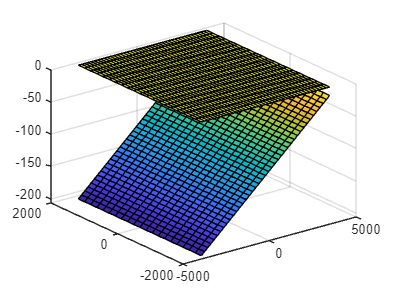

clear all;clc
%海底平面作图
alpha=pi/120;
x=[-2:0.1:2]*1852;
y=[-1:0.1:1]*1852;
[X,Y]=meshgrid(x,y);
Z=110-tan(alpha).*X;
surf(X,Y,-Z)
hold on
surf(X,Y,zeros(21,41))
print -dpng 第三问海底.png

% D0=110-tan(alpha)*2*1852
% syms beta W1(beta) W2(beta) lam(beta) mu(beta) d(beta) eta(beta) ga
% alpha=pi/120;%海底坡度
% theta=2*pi/3;%换能器开角
% % tan(ga)=sin(beta)*tan(alpha);%γ角
% W1(beta)=sqrt(3)*cos(ga)/(cos(2*ga)+sqrt(3)/2)*(D0+(4*sin(beta)^2*tan(beta)+2*sin(beta)^2+2)/tan(beta)*tan(alpha)*1852);
% W2(beta)=sqrt(3)*cos(ga)/(cos(2*ga)+sqrt(3)/2)*(D0+2*1852/tan(beta)*tan(alpha));
% lam(beta)=cos(theta/2+ga)/cos(ga);
% mu(beta)=cos(theta/2-ga)/cos(ga);
% d(beta)=(4-2/tan(beta))*sin(beta)*1852;
% eta(beta)=1-d/(lam*W1+mu*W2)
% eqs=[eta-0.2<0 beta>0 beta<pi tan(ga)==sin(beta)*tan(alpha)];
% S=solve(eqs,[beta,ga],"ReturnConditions",true)